# Nonlinear Adaptive Control

## Van der Pol oscilator continous model simulation

[t, x] = ode23(@van_der_pol, [0 50], [-1 0.5]);

figure, 
plot(t, x(:, 1)); hold on; grid;
plot(t, sin(t));
xlabel("Timp [s]", "Interpreter","latex");
ylabel("Amplitudinea semnalului", "Interpreter","latex");
legend("Raspunsul sistemului", "Intrarea", "Interpreter", "latex");

## Van der Pol oscilator discrete model simulation

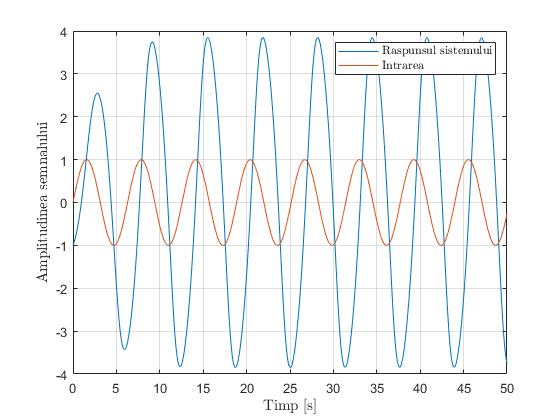

Ts = 0.01;
t = 0:Ts:50;
u = sin(t);
x = zeros(2, length(t));
mu = 0.1;

x0 = [-1; 0.5];
x(:, 1) = x0 + Ts*van_der_pol_derivatiave(x0, u(1), mu);

for i = 2:length(t)
    x(:, i) = x(:, i - 1) + Ts*van_der_pol_derivatiave(x(:, i - 1), u(i), mu);
end

figure, 
plot(t, x(1, :)); grid; hold on;
plot(t, u);
xlabel("Timp [s]", "Interpreter","latex");
ylabel("Amplitudinea semnalului", "Interpreter","latex");
legend("Raspunsul sistemului", "Intrarea", "Interpreter", "latex");

## Neural Network Based Adaptive Control

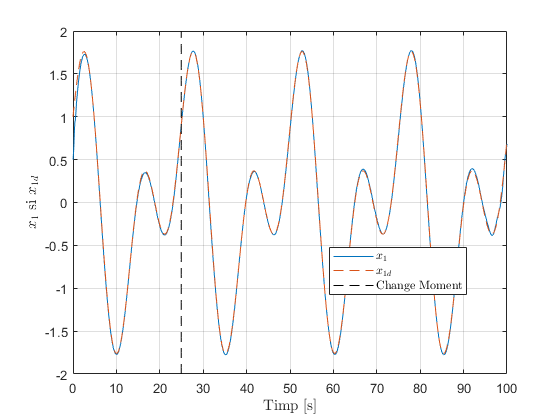

mu = 0.1;
Ac = diag([-1 -1]);
x0 = [0.5 0.5]';
lr = 0.5;
gamma = 0.0001;

Ts = 0.05;
t = 0:Ts:100;
% desired trajectory
xd = [sin(0.5*t) + cos(0.25*t); 0.5*cos(0.5*t) - 0.25*sin(0.25*t)];

m = 20; % number of hidden neurons
n = 4; % number of inputs

% neural network weights
Vc = rands(m, n);
Wc = rands(1, m);

x = zeros(2, length(t));
e = zeros(2, length(t));

x(:, 1) = x0;
u = zeros(length(t), 1);

aux = floor(length(t)/2)/2;

for i = 1:length(t) - 1
    if i == aux
        mu = mu + 2;
    end
    e(:, i) = x(:, i) - xd(:, i);
    x_cnn = [e(:, i); xd(:, i)];
    
    % backpropagation
    dWc = e(:, i)'/Ac*ones(2, 1)*tanh(Vc*x_cnn)';   
    duda = Wc*(eye(m) - diag(tanh(Vc*x_cnn).^2)); % Wc.*tanh_derivative(Vc*x_cnn)'
    dVc = (e(:, i)'/Ac*ones(2, 1)*duda)'*x_cnn';
    
    Wc = Wc - lr*dWc - gamma*norm(e(:, 1))*Wc;
    Vc = Vc - lr*dVc - gamma*norm(e(:, 1))*Vc;
    
    % inference
    u(i) = -Wc*tanh(Vc*x_cnn);
    
    x(:, i + 1) = x(:, i) + Ts*van_der_pol_derivatiave(x(:, i), u(i), mu);    
end

figure, 
plot(t, x(1, :)); hold on; grid;
plot(t, xd(1, :), "--");
plot(t(aux)*ones(length(t), 1), t/25 - 2, "Color", "Black", "LineStyle","--");
xlabel("Timp [s]", "Interpreter","latex");
ylabel("$x_1$ si $x_{1d}$", "Interpreter","latex");
legend("$x_1$", "$x_{1d}$", "Change Moment", "Interpreter", "Latex", "Location","best");

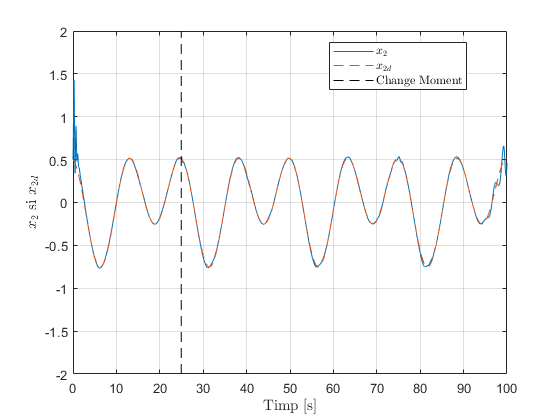


figure, 
plot(t, x(2, :)); hold on; grid;
plot(t, xd(2, :), "--");
plot(t(aux)*ones(length(t), 1), t/25 - 2, "Color", "Black", "LineStyle","--");
xlabel("Timp [s]", "Interpreter","latex");
ylabel("$x_2$ si $x_{2d}$", "Interpreter","latex");
legend("$x_2$", "$x_{2d}$", "Change Moment", "Interpreter", "Latex", "Location","best");

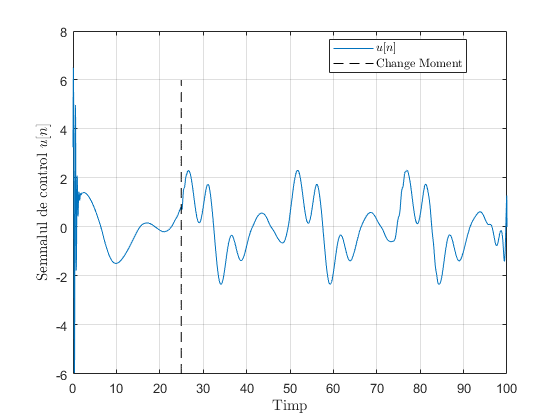


figure,
plot(t, u); grid; hold on;
plot(t(aux)*ones(length(t), 1), t*0.12 - 6, "Color", "Black", "LineStyle","--");
xlabel("Timp", "Interpreter","latex");
ylabel("Semnalul de control $u[n]$", "Interpreter","latex");
legend("$u[n]$", "Change Moment", "Interpreter", "Latex", "Location","best");

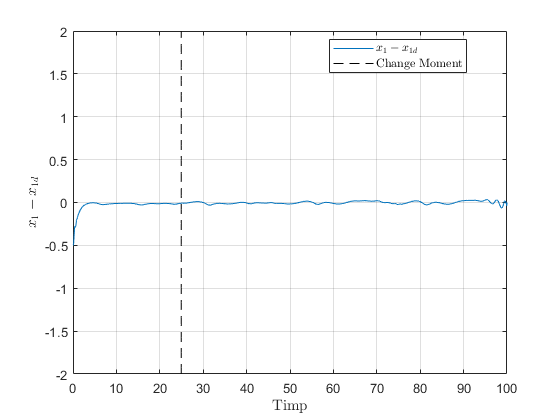


figure, 
plot(t, e(1, :)); grid; hold on;
plot(t(aux)*ones(length(t), 1), t/25 - 2, "Color", "Black", "LineStyle","--");
xlabel("Timp", "Interpreter","latex");
ylabel("$x_1 - x_{1d}$", "Interpreter","latex");
legend("$x_1 - x_{1d}$", "Change Moment", "Interpreter", "Latex", "Location","best");

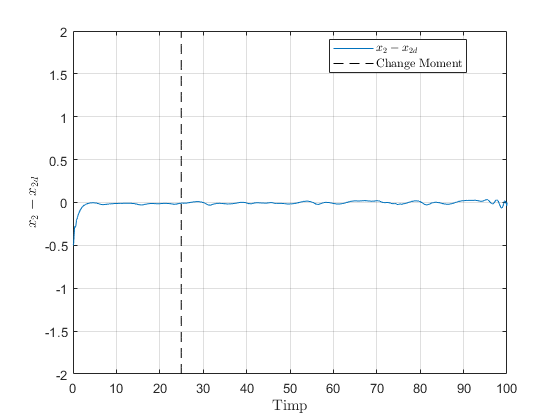


figure, 
plot(t, e(1, :)); grid; hold on;
plot(t(aux)*ones(length(t), 1), t/25 - 2, "Color", "Black", "LineStyle","--");
xlabel("Timp", "Interpreter","latex");
ylabel("$x_2 - x_{2d}$", "Interpreter","latex");
legend("$x_2 - x_{2d}$", "Change Moment", "Interpreter", "Latex", "Location","best");

function dx = van_der_pol(t, x)
    mu = 0.1;
    u = sin(t);
    
    dx = [x(2);
          mu*(1 - x(1)^2)*x(2) - x(1) + u];
end

function dx = van_der_pol_derivatiave(x, u, mu)
    dx = [x(2);
          mu*(1 - x(1)^2)*x(2) - x(1) + u];
end

function y = tanh(x)
    y = (exp(x) - exp(-x))./(exp(x) + exp(-x));
end

function y = tanh_derivative(x)
    y = (1 - tanh(x).^2);
end